# Dinámica de un Proyectil

Este script establece un modelo simple para la simulación del movimiento de un proyectil en dos dimensiones, bajo la influencia de la gravedad. 

clear all
close all

### Parámetros iniciales

v0 = 20;      % Velocidad inicial en m/s
%theta = pi/4; % Ángulo de disparo en radianes
g = 9.8;      % Aceleración debida a la gravedad (m/s^2)
x0 = 0;       % Posición inicial en el eje x
y0 = 20;      % Posición inicial en el eje y
theta = pi/4; % Ángulo de disparo (45 grados)


## Configuración de las opciones para la integración numérica

options = odeset('RelTol',1e-4,'AbsTol',1e-4);


### Definición del modelo dinámico

`model`: Define la **función anónima** que describe las ecuaciones diferenciales para el movimiento del proyectil.

- `v0 * cos(theta)` es la **componente de velocidad en el eje x** (horizontal).

- `v0 * sin(theta) - g * t` es la **componente de velocidad en el eje y** (vertical), considerando la gravedad, que actúa sobre la velocidad a lo largo del tiempo ttt.

model=@(t,x) [v0*cos(theta);v0*sin(theta)-g*t]; 

## Definición del tiempo de simulación

`t_span`: Define el intervalo de tiempo para la simulación, desde t=0 hasta t=5t segundos, con un paso de 0.001 segundos. Este paso pequeño asegura una alta resolución temporal en la simulación.

t_span = [0:.001:5];  % Tiempo de simulación

## Resolución numérica del sistema de ecuaciones diferenciales

- `ode45`: Utiliza el **método de Runge-Kutta de cuarto orden** para resolver el sistema de ecuaciones diferenciales que describe el movimiento del proyectil.

- `model`: La función que describe el sistema de ecuaciones diferenciales.

- `t_span`: El intervalo de tiempo en el que se realiza la simulación.

- `[x0 y0]`: Las condiciones iniciales de posición x e y del proyectil.

- `options`: Las opciones definidas anteriormente para controlar la precisión del cálculo.

El resultado de `ode45` es:

- `t`: Un vector que contiene los **instantes de tiempo** en los que se evalúa la solución.

- `X`: Una matriz que contiene las **soluciones de las posiciones** del proyectil en los ejes x e y a lo largo del tiempo. Cada fila de `X` contiene una pareja de valores [x,y] para un tiempo ttt.

[t,X]=ode45(model,t_span,[x0 y0],options);

## Extraer las soluciones

x = X(:, 1);  % Posición en x
y = X(:, 2);  % Posición en y

% Encontrar la altura máxima
[~, idx_max_height] = max(y);  % Índice de la altura máxima
max_height = y(idx_max_height);  % Altura máxima alcanzada

% Encontrar la distancia de impacto (última posición en x)
impact_idx = find(y < 0, 1);  % Primer índice donde y < 0
impact_distance = x(impact_idx);  % Distancia de impacto en x

% Encontrar el tiempo de impacto (cuando y < 0)
impact_time = t(find(y < 0, 1));  % Tiempo en que el proyectil impacta el suelo


## Crear la figura para la animación

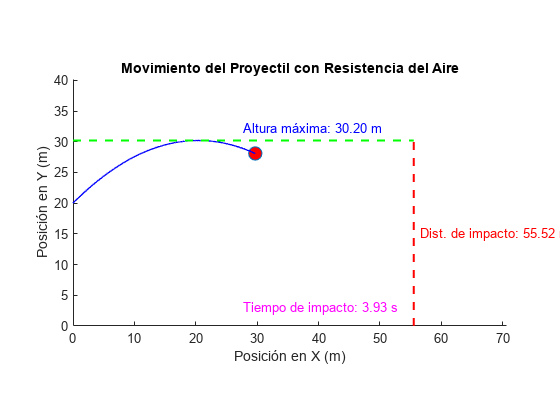

figure;
hold on;
axis equal;
xlim([0 max(x)]);        % Limitar el eje X
ylim([0 max(y) + 10]);   % Limitar el eje Y
xlabel('Posición en X (m)');
ylabel('Posición en Y (m)');
title('Movimiento del Proyectil con Resistencia del Aire');


% Crear el gráfico del proyectil (como un punto rojo)
h = plot(x0, y0, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);

% Crear la línea para el rastro (como una línea azul)
rastro = plot(NaN, NaN, 'b-', 'LineWidth', 1);

% Añadir líneas de referencia para la altura máxima y la distancia de impacto
line([0 impact_distance], [max_height max_height], 'Color', 'g', 'LineStyle', '--', 'LineWidth', 1.5);  % Línea de altura máxima
line([impact_distance impact_distance], [0 max_height], 'Color', 'r', 'LineStyle', '--', 'LineWidth', 1.5);  % Línea de distancia de impacto

% Añadir texto para la altura máxima, distancia de impacto y tiempo de impacto
text(impact_distance / 2, max_height + 2, sprintf('Altura máxima: %.2f m', max_height), 'Color', 'b', 'FontSize', 10);
text(impact_distance + 1, max_height / 2, sprintf('Dist. de impacto: %.2f m', impact_distance), 'Color', 'r', 'FontSize', 10);
text(impact_distance / 2, 3, sprintf('Tiempo de impacto: %.2f s', impact_time), 'Color', 'm', 'FontSize', 10);

% Animación usando drawnow
for i = 1:20:length(t)
   
    % Actualizar la posición del proyectil en el gráfico
    set(h, 'XData', x(i), 'YData', y(i));
    
xlim([0.0 70.7])
ylim([-0.3 40.2])
zlim([-1.00 1.00])

    % Actualizar el rastro del proyectil (línea azul)
    set(rastro, 'XData', x(1:i), 'YData', y(1:i));
    
    % Actualizar la figura en tiempo real
    drawnow;
    
    % Detener la animación si el proyectil toca el suelo
    if y(i) < 0
        break;
    end
end